# FAR 23 Landing Distance Requirements

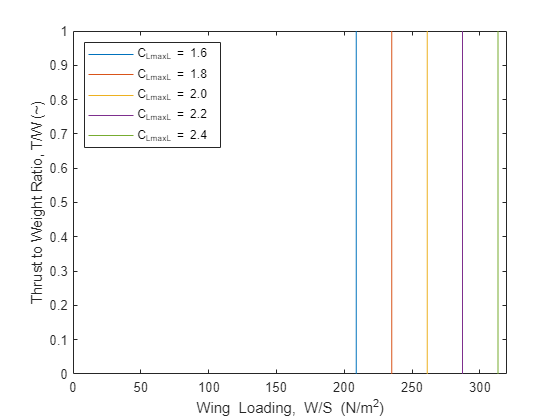

% FAR 23
clc
clear all


rho_1 = 1.225; % Density at sea level kg/m^3
T_1C = 15; % Standard temperature at sea level in C
p_1 = 101325; % Standard sea level pressure in Pa
C_LmaxL = [1.6, 1.8, 2.0, 2.2, 2.4]; % C_LmaxL range of values
WL2WTO = 1; % Landing weight to take off weight ratio
S_L = 250; % Landing distance in m

S_LG = S_L/1.938; % Landing ground distance in m
S_LGft = convlength(S_LG,'m','ft'); % Convert m to ft
V_SLkts = sqrt(S_LGft/0.265); % Landing stall speed in kts
V_SL = (1852/3600)*V_SLkts; % Convert kts to m/s
V_A = 1.3 * V_SL; % Approach speed in m/s from CS22

% Items of note
% Landing configuration stall speeds (V_SL)v must never exceed
%   22.2 m/s with retracted air brakes, maximum weight, and empty water ballast tanks
%   25 m/s with retracted air brakes, maximum weight, with water in ballast tanks
%   26.4 m/s with deployed air brakes, maximum weight, with water in ballast tanks

%Find rho_2 at ISA+10C
T_1 = T_1C + 273.15; % Convert Celcius to Kelvin
T_2 = T_1 + 10 + 273.15; % ISA temp +10C in K
p_2 = p_1; % Pressure at ISA+10C
rho_2 = rho_1 * (T_1/T_2); % Density at ISA +10C in kg/m^3

W2S = (0.5 .* rho_2 .* V_SL^2 .* C_LmaxL) ./ WL2WTO;

W2P = linspace(0,1,100);
W2S_L1 = ones(size(W2P)) .* W2S(1,1); 
W2S_L2 = ones(size(W2P)) .* W2S(1,2);
W2S_L3 = ones(size(W2P)) .* W2S(1,3); 
W2S_L4 = ones(size(W2P)) .* W2S(1,4);
W2S_L5 = ones(size(W2P)) .* W2S(1,5);

figure(1)
plot(W2S_L1,W2P)
hold on
plot(W2S_L2,W2P)
hold on
plot(W2S_L3,W2P)
hold on
plot(W2S_L4,W2P)
hold on
plot(W2S_L5,W2P)

xlabel("Wing Loading, W/S (N/m^2)");
ylabel("Power Loading, T/W (~)");
xlim([0, 320]);
ylim([0,1]);

legend('C_{LmaxL} = 1.6','C_{LmaxL} = 1.8','C_{LmaxL} = 2.0','C_{LmaxL} = 2.2','C_{LmaxL} = 2.4', Location="northwest")

hold off